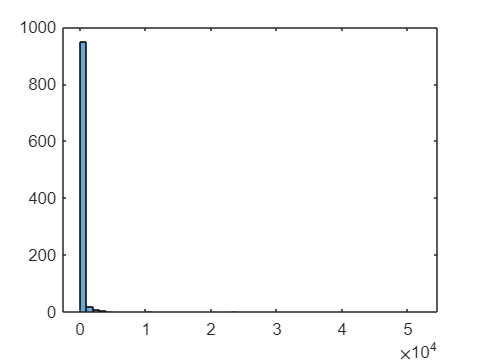

X = lognrnd(2,3,1000,5000);
histogram(X(:,70))

X = -log(rand(100,1)) %- Log de una uniforme es una exponencial

X =     0.1516
    0.6890
    0.9168
    0.2804
    0.2995
    1.1013
    1.4079
    0.2930
    0.1361
    0.1380


m = min(X);
M = max(X);
x = m:0.1:M;

x =     0.0049    0.1049    0.2049    0.3049    0.4049    0.5049    0.6049    0.7049    0.8049    0.9049    1.0049    1.1049    1.2049    1.3049    1.4049    1.5049    1.6049    1.7049    1.8049    1.9049    2.0049    2.1049    2.2049    2.3049    2.4049    2.5049    2.6049    2.7049    2.8049    2.9049    3.0049    3.1049    3.2049    3.3049    3.4049    3.5049    3.6049    3.7049    3.8049    3.9049    4.0049    4.1049    4.2049


yt = expcdf(x);

yt =     0.0048    0.0995    0.1852    0.2628    0.3329    0.3964    0.4538    0.5058    0.5528    0.5954    0.6339    0.6687    0.7003    0.7288    0.7546    0.7779    0.7991    0.8182    0.8355    0.8512    0.8653    0.8781    0.8897    0.9002    0.9097    0.9183    0.9261    0.9331    0.9395    0.9452    0.9505    0.9552    0.9594    0.9633    0.9668    0.9699    0.9728    0.9754    0.9777    0.9799    0.9818    0.9835    0.9851


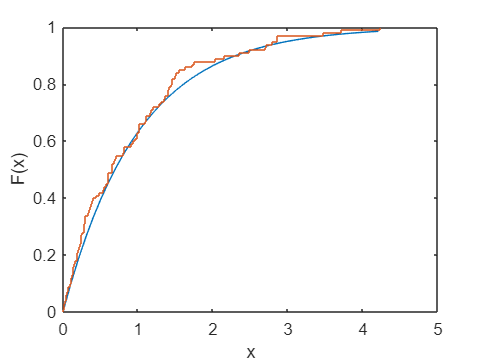

plot(x,yt)
hold on
ecdf(X)

x = linspace(0,2*pi,100);
y = sin(3*X)+0.5*randn(1,100);
plot(x,y)

corr(x',y')

ans = -0.1840

X1 = randn(1000,2);
X2 = 10 + randn(800,2);
X = [X1
    X2];
corr(X(:,1),X(:,2));fitlm(X(:,2),X(:,1))

ans = 0.9610

## Integral Montecarlo

M = exp(2);
a = 1;
b = 2;
N = 1000

N = 1000

valor_real = exp(2) - exp(1)

valor_real = 4.6708

x = a + (b-a)*rand(N,1);
y = 0 + M*rand(N,1);
I = mean(y<=exp(x));
Int = I*M*(b-a)

Int = 4.6699

## Semana 7

n = 1000
X= rand(n,2);
media = mean(X);
XC = X-media;
d =[]
for j = 1:n
    d(j) = norm(XC(j,:),2);
end
p =prctile(d,50)
I = find(d<p)
plot(XC(:,1),X(:,2),'o')
hold on
plot(XC(I,1),X(I,2),'o')
hold off8